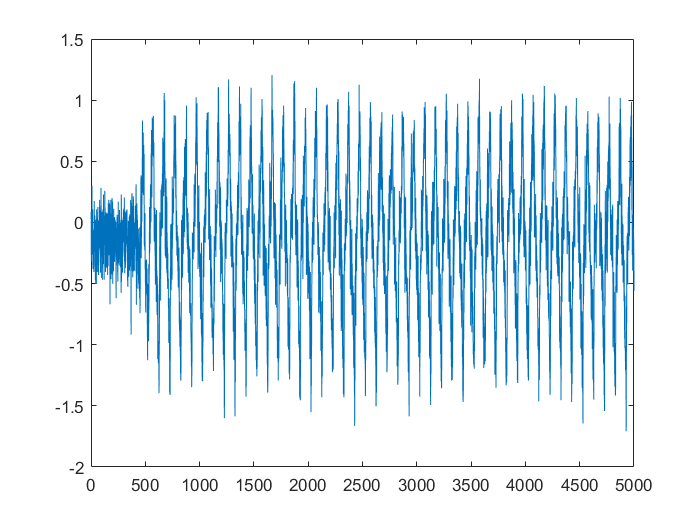

% clear
load("files/switchingAFCMulti.mat")
y = data.y(1:5000);
plot(y)


Fs = 5000;

[f, p] = fftFunc(Fs, length(y), y);

plot(f, p)
ylim([-2, 2])

sum(p)

ans = 23.1308

sum(p(p>0.02))

ans = 3.9975

power_density = sum(p(p>0.01))/sum(p)

power_density = 0.2720

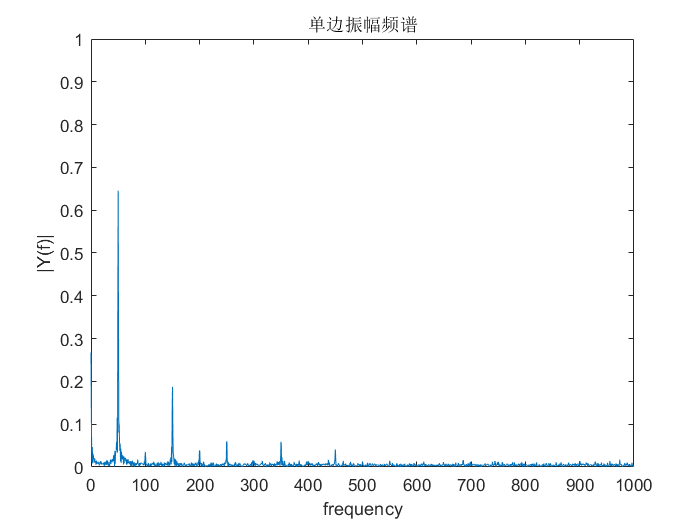


title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 1000])
ylim([0, 1])

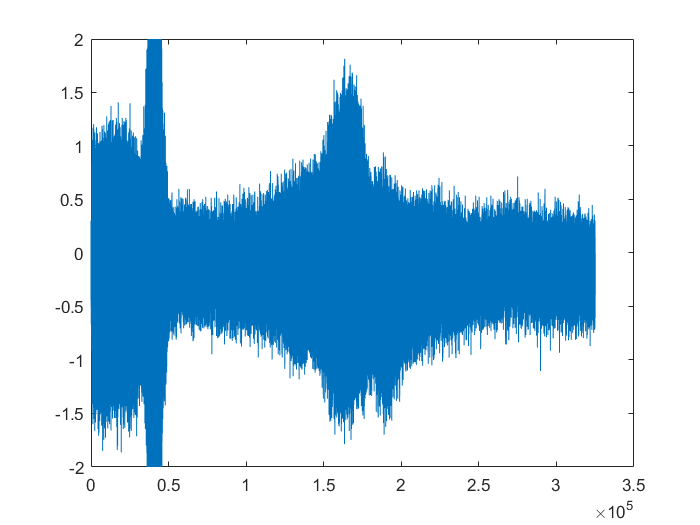

% clear
load("files/bandpass.mat")
load("files/switchingAFCMulti.mat")
y = data.y(1:end);
plot(y)
ylim([-2, 2])

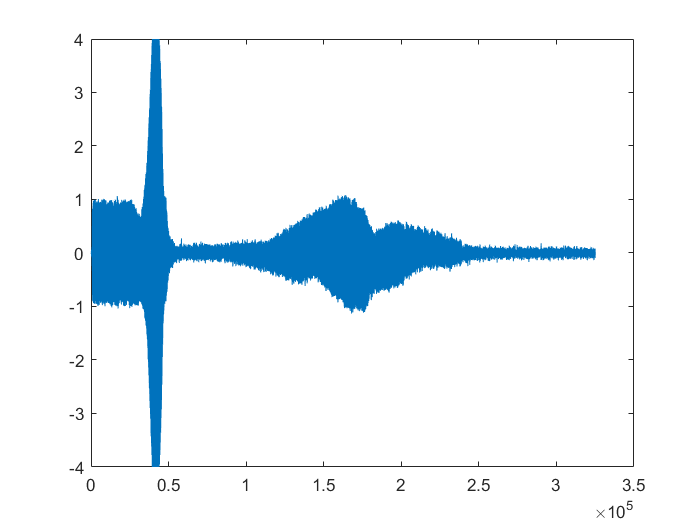


res = filter(bandpass50,y) + filter(bandpass100,y) + filter(bandpass150,y) + filter(bandpass200,y);
% res = filter(bandpass50,y);
plot(res)
ylim([-4, 4])

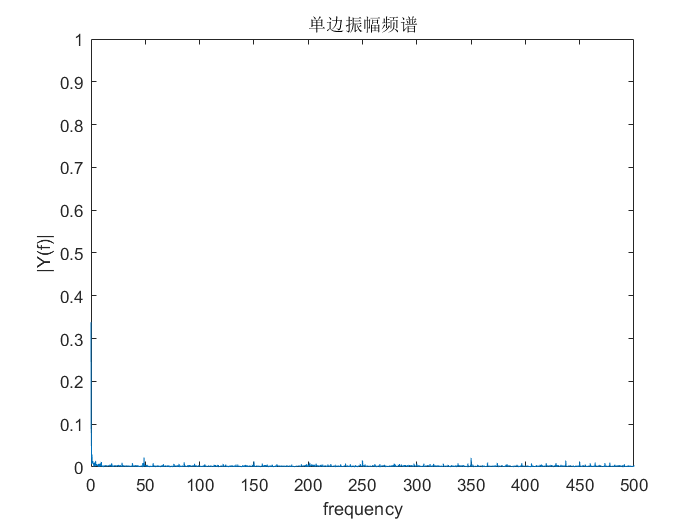

Fs = 5000;

y = data.y(300000:end);

[f, p] = fftFunc(Fs, length(y), y);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 500])
ylim([0, 1])

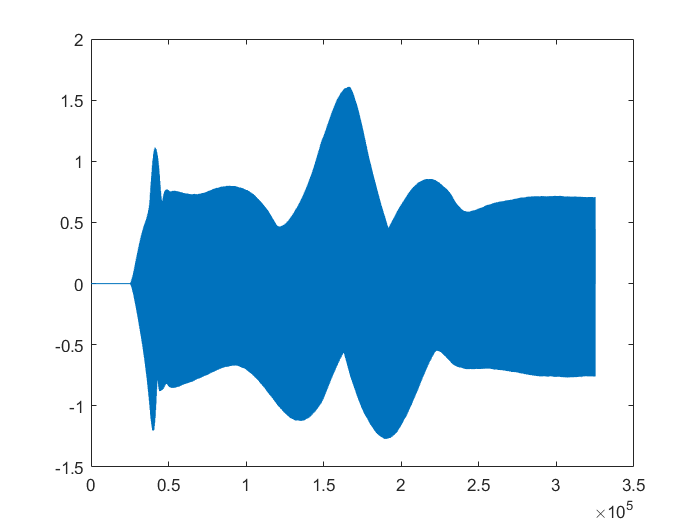




u = data.u(1:end);
plot(u)

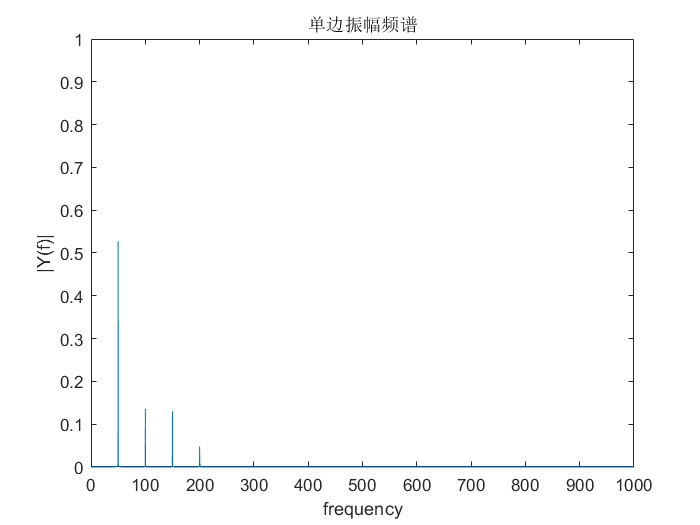

Fs = 5000;

[f, p] = fftFunc(Fs, length(u), u);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 1000])
ylim([0, 1])

function [f, p] = fftFunc(Fs, L, y)
T= 1/Fs; %采样时间
t = (0:L-1)*T; %时间向量
NFFT = 2^nextpow2(L);
Y = fft(y,NFFT)/L;
f = Fs/2*linspace(0,1,NFFT/2);
p = 2*abs(Y(1:NFFT/2));
end